%NISoC Load, Parse, and Plot

filename1 = ('plots/20210804-210129_QFP8_NeuroCube_lab_pluggedin_gain_60_BW111_current_clamp_ND18_neuron10_Ch15.csv')

filename1 = 'plots/20210804-210129_QFP8_NeuroCube_lab_pluggedin_gain_60_BW111_current_clamp_ND18_neuron10_Ch15.csv'

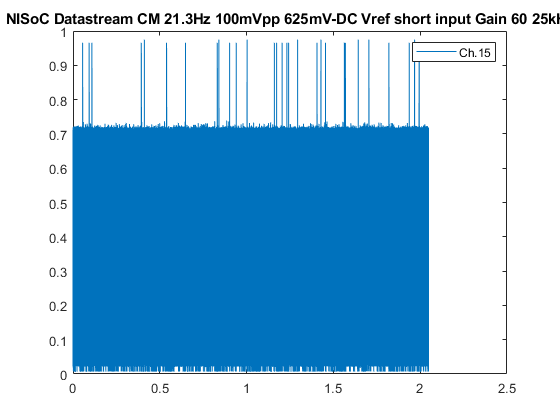

dt1 = dlmread(filename1,',',0,0);
data{1}.data    = dt1(1,:) * 1.2/4095;                 % convert decimal to volts
%data{1}.rst     = dt1(2,:);
%data{1}.cds     = dt1(3,:);

gain            = 60;
CDS_mode        = true;
data{1}.fs      = 25000;                          % set sampling frequency 
data{1}.time    = 0:1/data{1}.fs:(length(data{1}.data)-1)*1/data{1}.fs;   

figure(1);
h = plot(data{1}.time,data{1}.data);
title('NISoC Datastream CM 21.3Hz 100mVpp 625mV-DC Vref short input Gain 60 25kHz');
%xlim([0 0.1])
legend('Ch.15')

## Spilt Datastream to Real sample and Reference Sample

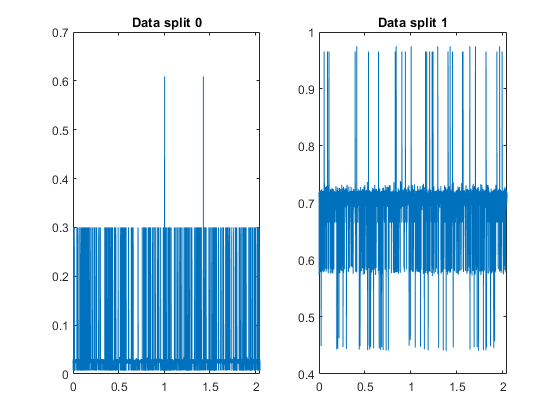

if CDS_mode
   
    data{2}.data    = data{1}.data(2:2:end);    % should be the real data
    data{2}.time    = data{1}.time(2:2:end);
    data{2}.fs      = round(data{1}.fs/2);
    data{3}.data    = data{1}.data(1:2:end);    % should be reference data
    data{3}.time    = data{1}.time(1:2:end);
    data{3}.fs      = round(data{1}.fs/2);
    
    figure(2); subplot(1,2,1);
    plot(data{2}.time,data{2}.data);
    title('Data split 0');
    %ylim([0.594 0.602])
    %xlim([0 0.1]);
    subplot(1,2,2);
    plot(data{3}.time,data{3}.data);
    title('Data split 1');
    %xlim([0 0.1]);
    %ylim([0.594 0.602])
end

Data Split 0 appears to be the Real signal with a 60 Hz 13 mV_{PP} signal. Data Split 1 would therefore be the CDS References signal which has a narrow region centered at 597 mV with 2 mV_{PP} noise and broad regions containing the 60Hz signal at 13 mV_{PP}, pushed down by a 5.3 mV_{PP} signal. **The Reference sample captured during digital double sample has 60 Hz noise! **

## Generate CDS dataset


$$V_{corrected} = V_{sample,n} - \frac{1}{2}V_{ref,n-1} -\frac{1}{2}V_{vref,n+1}$$


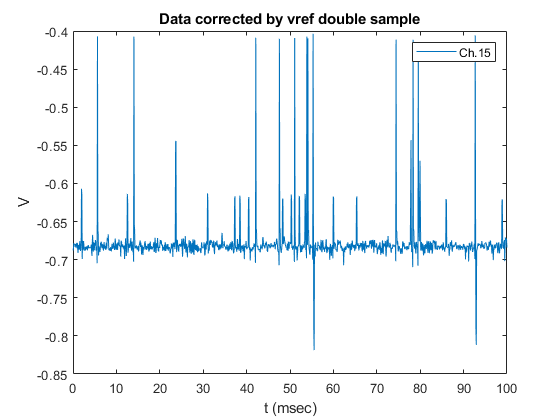

%data{3}.data(:) = 0.6;     % set static Vref Reference data set
if CDS_mode
    data{4}.data = zeros(length(data{2}.data),1);
    
    for i = 1:length(data{2}.data)                         % iterate through datastream
        if (i == 1)
            data{4}.data(i) = (data{2}.data(i)-1.0*data{3}.data(i));     % equivalent to Vsam(n) - Vref(n+1)
        else
            data{4}.data(i) = (data{2}.data(i)-0.5*data{3}.data(i-1)-0.5*data{3}.data(i));    % create corrected data set
        end
    end
    
    data{4}.fs      = data{2}.fs;                         % adjust sampling rate 
    data{4}.time    = data{2}.time;                       % use the sample set time for corrected set                              
    
    figure(20);
    h = plot(data{4}.time*1000,(data{4}.data));
    title('Data corrected by vref double sample');
    ax = ancestor(h, 'axes');
    ax.YAxis.Exponent = 0;
    xlim([0 100]);
    legend('Ch.15');
    xlabel('t (msec)');
    ylabel('V');
end

The corrected dataset is generated by subtracting half of the previous reference sample and half of the next reference sample from the current real sample. In the figure, we see a DC correction towards 0 V revealing a 60Hz signal that was approximately -5.0 mV off set from Vref. **Noise from the digital double sample is injected into the correct dataset!**

## Filter 60Hz noise

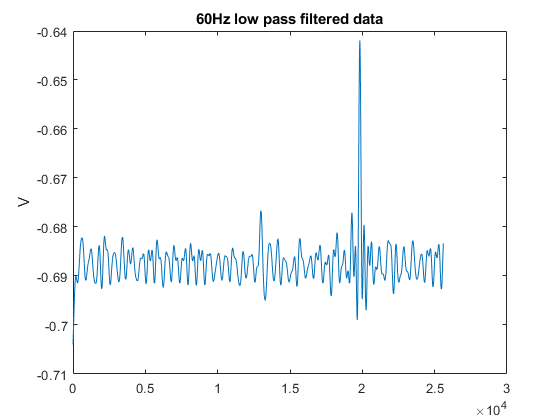

lpfilt = designfilt('lowpassiir', 'FilterOrder', 20, 'HalfPowerFrequency', 50, 'SampleRate', 12500);
test = filtfilt(lpfilt, data{4}.data);
figure;
plot(test);
ylabel('V');
title('60Hz low pass filtered data')

## PSD (periodogram) 

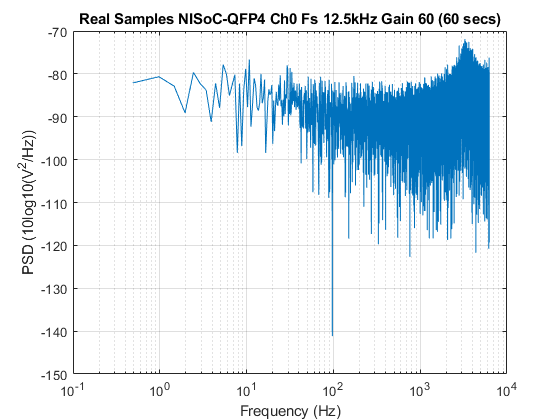

if CDS_mode
    [dPD, f, Vnrms] = psd_rms(data{2}.data, data{2}.fs,gain,1, 2);
    faidx = find(f(f<1));
    if (length(faidx) == 0)
        faidx = 1;
    else
        faidx = faidx(1);
    end
    fzidx = find(f(f<12500));
    fzidx = fzidx(end);
    [dPD, f, Vnrms] = psd_rms(data{2}.data, data{2}.fs,gain,faidx, fzidx);
else
    [dPD, f, Vnrms] = psd_rms(data{1}.data, data{1}.fs,gain,1, 2);
    faidx = find(f(f<1));
    if (length(faidx) == 0)
            faidx = 1;
    else
        faidx = faidx(end);
    end
    fzidx = find(f(f<12500));
    fzidx = fzidx(end);
    [dPD, f, Vnrms] = psd_rms(data{1}.data, data{1}.fs,gain, faidx, fzidx);
end
figure(27);
%hold on
plot(f, 10*log10(dPD));
grid on
title(['Real Samples NISoC-QFP4 Ch0 Fs 12.5kHz Gain ',num2str(gain),' (60 secs)']); 
xlabel('Frequency (Hz)');
ylabel('PSD (10log10(V^{2}/Hz))');
set(gca, 'XScale', 'log') 
hold off


% Noise calculation presented in uVrms
disp(['Vrms calculation: ',num2str(Vnrms)]);

Vrms calculation: 0.0047673


## PSD (periodogram) 

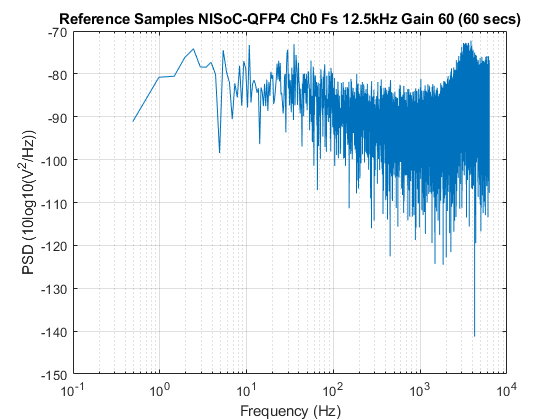

if CDS_mode
    [dPD, f, Vnrms] = psd_rms(data{3}.data, data{3}.fs,gain,1, 2);
    faidx = find(f(f<1));
    if (length(faidx) == 0)
        faidx = 1;
    else
        faidx = faidx(1);
    end
    fzidx = find(f(f<12500));
    fzidx = fzidx(end);
    [dPD, f, Vnrms] = psd_rms(data{3}.data, data{3}.fs,gain,faidx, fzidx);
else
    [dPD, f, Vnrms] = psd_rms(data{1}.data, data{1}.fs,gain,1, 2);
    faidx = find(f(f<1));
    if (length(faidx) == 0)
            faidx = 1;
    else
        faidx = faidx(end);
    end
    fzidx = find(f(f<12500));
    fzidx = fzidx(end);
    [dPD, f, Vnrms] = psd_rms(data{1}.data, data{1}.fs,gain, faidx, fzidx);
end
figure(28);
%hold on
plot(f, 10*log10(dPD));
grid on
title(['Reference Samples NISoC-QFP4 Ch0 Fs 12.5kHz Gain ',num2str(gain),' (60 secs)']); 
xlabel('Frequency (Hz)');
ylabel('PSD (10log10(V^{2}/Hz))');
set(gca, 'XScale', 'log') 
hold off


% Noise calculation presented in uVrms
disp(['Vrms calculation: ',num2str(Vnrms)]);

Vrms calculation: 0.0048394


## PSD (periodogram) 

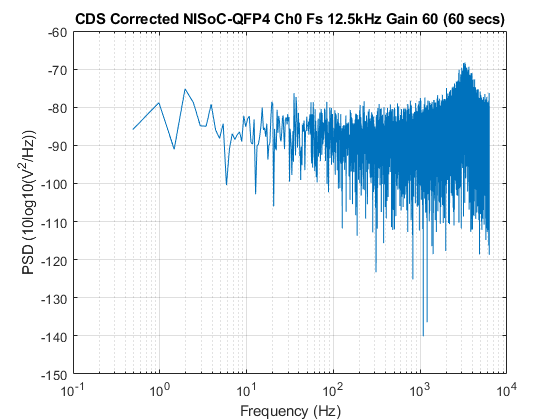

if CDS_mode
    [dPD, f, Vnrms] = psd_rms(data{4}.data, data{4}.fs,gain,1, 2);
    faidx = find(f(f<1));
    if (length(faidx) == 0)
        faidx = 1;
    else
        faidx = faidx(1);
    end
    fzidx = find(f(f<12500));
    fzidx = fzidx(end);
    [dPD, f, Vnrms] = psd_rms(data{4}.data, data{4}.fs,gain,faidx, fzidx);
else
    [dPD, f, Vnrms] = psd_rms(data{1}.data, data{1}.fs,gain,1, 2);
    faidx = find(f(f<1));
    if (length(faidx) == 0)
            faidx = 1;
    else
        faidx = faidx(end);
    end
    fzidx = find(f(f<12500));
    fzidx = fzidx(end);
    [dPD, f, Vnrms] = psd_rms(data{1}.data, data{1}.fs,gain, faidx, fzidx);
end
figure(29);
%hold on
plot(f, 10*log10(dPD));
grid on
title(['CDS Corrected NISoC-QFP4 Ch0 Fs 12.5kHz Gain ',num2str(gain),' (60 secs)']); 
xlabel('Frequency (Hz)');
ylabel('PSD (10log10(V^{2}/Hz))');
set(gca, 'XScale', 'log') 
hold off


% Noise calculation presented in uVrms
disp(['Vrms calculation: ',num2str(Vnrms)]);

Vrms calculation: 0.0064533


[dPD, f, Vnrms1] = psd_rms(data{3}.data, data{3}.fs,gain,3, 122);
[dPD, f, Vnrms2] = psd_rms(data{3}.data, data{3}.fs,gain,126, 12801);
Vnrmstot = Vnrms1 + Vnrms2;
disp(Vnrmstot)

rownames = {'Real Sample','Ref Sample','Corrected'};
legend(rownames)

Over a 12.5kHz BW, the rms noise for each data set are as follows:

% table
Vrms_vals = [0.0042;0.0041;0.0045];
table(Vrms_vals,'RowNames',rownames')

## Save Data of choice to CSV

%writematrix(data{4}.data,'CDS_subtracted_NISoC_QFP4_ch0_shorted_input_vref_CDS_gain_60secs.csv')


## PSD RMS Function

function [dPD, f, Vnrms] = psd_rms(data,Fs,gain,faidx,fzidx)
    N = length(data);
    dFT = fft(data);       % fft
    dFT = dFT(1:N/2+1);     % DC to Nyquist 
    dFT = dFT/gain;
    dPD = (1/(Fs*N)) * abs(dFT).^2;  % periodogram
    dPD(2:end-1) = 2*dPD(2:end-1);      % factor of 2 to conserve power
    f = 0:Fs/N:Fs/2;
    
    % Noise calculation presented in uVrms
    f(fzidx);
    df = f(fzidx) - f(fzidx-1);
    BW = faidx:fzidx; 
    Vnrms = sqrt(sum(dPD(BW)*(df)));   
end